# Assessing bias and variance in mixed effects model estimates using simulation

This script simulates power and false positive rates given a set of input parameters.  

It strings together several scripts we've used so far. it is a "wrapper" for 

sim_mixedfx_fpr_power_bias_matlablme

with different values for sample size.

**About sim_mixedfx_fpr_power_bias_matlablme**

sim_mixedfx_fpr_power_bias_matlablme is a wrapper that generates and fits data for each of a series of iterations, and then collects results (bias, variance, rates of positive findings).  It uses these functions:

    sim_generate_mixedfx_data1 generates a dataset given parameters, and assuming normally distributed errors

    matlabLMEstats runs the mixed effects model and collects selected output statistics

    get_sim_stats collects tables of statistics across iterations

The false positive rates in this simulation are assessed when the true fixed effects are all zero, and other random effects are unchanged.

We've built up these functions over the last several scripts so you can see how they work and modify them.  They are designed to be modular.

You can:

1 - Run this script with different inputs, including sample sizes (between/within), variances, fixed effects, regressor types

2 - Copy this script and modify the matlabLMEstats function to return the summary statistics for any mixed effects model you like

### Specify input parameters

n_i = 20;           % len
m = 5;              % sub
p = 2;              % num params
b_g = [1 3]';       % fixed effects: Intercept and slope    
s2 = 25;            % residual var
U_g = [3 0; 0 9];   % Cov matrix of random intercept and slope
regressortype = 'continuous';

% These are params whose estimates we will compare later in the report
fixedint = b_g(1);
fixedslope = b_g(2); 
 
withinerr_std = sqrt(s2);

randintvar = U_g(1, 1);
randslopevar = U_g(2, 2);
 

### **Test run**

Generate a dataset, fit the model, and plot the results

iter = 50;
[sig_table, bias_variance_table] = sim_mixedfx_fpr_power_bias_matlablme(iter, m, n_i, p, b_g, s2, U_g, regressortype);

Elapsed time is 5.988171 seconds.



% [sig_table, bias_variance_table] = sim_mixedfx_fpr_power_bias_glmfitmulti(iter, m, n_i, p, b_g, s2, U_g, regressortype);


### Power, FPR, bias, and variance as a function of number of subjects

This cell block runs the simulation:

iter = 1000;
m_vals = [5 10 20 40 100 200];

[sig_tables, bv_tables] = deal({});
eval_time_per_model = zeros(1, length(m_vals));
b_g_null = zeros(size(b_g)); % global null w/no fixed effects

for i = 1:length(m_vals)

    timekeeper = clock;

    [sig_tables{i}, bv_tables{i}] = sim_mixedfx_fpr_power_bias_matlablme(iter, m_vals(i), n_i, p, b_g, s2, U_g, regressortype);

    eval_time_per_model(i) = etime(clock, timekeeper) ./ iter;

    fpr_tables{i} = sim_mixedfx_fpr_power_bias(iter, m_vals(i), n_i, p, b_g_null, s2, U_g, regressortype);

end

Elapsed time is 11.602185 seconds.
Elapsed time is 22.716176 seconds.
Elapsed time is 34.063690 seconds.
Elapsed time is 44.606224 seconds.
Elapsed time is 56.188908 seconds.
Elapsed time is 67.909896 seconds.
Elapsed time is 78.808524 seconds.
Elapsed time is 89.634901 seconds.
Elapsed time is 100.354697 seconds.
Elapsed time is 111.254501 seconds.
Elapsed time is 111.254723 seconds.


Elapsed time is 10.385257 seconds.
Elapsed time is 20.822406 seconds.
Elapsed time is 31.805624 seconds.
Elapsed time is 42.227807 seconds.
Elapsed time is 53.012540 seconds.
Elapsed time is 63.447883 seconds.
Elapsed time is 74.196100 seconds.
Elapsed time is 85.065982 seconds.
Elapsed time is 96.475482 seconds.
Elapsed time is 107.799030 seconds.
Elapsed time is 107.799224 seconds.


Elapsed time is 9.419436 seconds.
Elapsed time is 18.542678 seconds.
Elapsed time is 27.994190 seconds.
Elapsed time is 37.602098 seconds.
Elapsed time is 47.228484 seconds.
Elapsed time is 56.778485 seconds.
Elapsed time is 66.139479 seconds.
Elapsed time is 75.425137 seconds.
Elapsed time is 84.987322 seconds.
Elapsed time is 94.361636 seconds.
Elapsed time is 94.361884 seconds.


Elapsed time is 9.359920 seconds.
Elapsed time is 18.773190 seconds.
Elapsed time is 28.059127 seconds.
Elapsed time is 38.004453 seconds.
Elapsed time is 47.308586 seconds.
Elapsed time is 56.756638 seconds.
Elapsed time is 66.011139 seconds.
Elapsed time is 76.041239 seconds.
Elapsed time is 85.757115 seconds.
Elapsed time is 95.191679 seconds.
Elapsed time is 95.191817 seconds.


Elapsed time is 9.228823 seconds.
Elapsed time is 18.505631 seconds.
Elapsed time is 27.676323 seconds.
Elapsed time is 36.852706 seconds.
Elapsed time is 46.136345 seconds.
Elapsed time is 55.488444 seconds.
Elapsed time is 64.721522 seconds.
Elapsed time is 73.943115 seconds.
Elapsed time is 83.195315 seconds.
Elapsed time is 92.398002 seconds.
Elapsed time is 92.398175 seconds.


Elapsed time is 9.158161 seconds.
Elapsed time is 18.502510 seconds.
Elapsed time is 27.657402 seconds.
Elapsed time is 36.857250 seconds.
Elapsed time is 46.015578 seconds.
Elapsed time is 55.338334 seconds.
Elapsed time is 64.699292 seconds.
Elapsed time is 73.935060 seconds.
Elapsed time is 83.503575 seconds.
Elapsed time is 92.810731 seconds.
Elapsed time is 92.810869 seconds.


Elapsed time is 9.859865 seconds.
Elapsed time is 19.492042 seconds.
Elapsed time is 29.079523 seconds.
Elapsed time is 38.612237 seconds.
Elapsed time is 48.199648 seconds.
Elapsed time is 57.668061 seconds.
Elapsed time is 67.433523 seconds.
Elapsed time is 77.444394 seconds.
Elapsed time is 87.281680 seconds.
Elapsed time is 97.131900 seconds.
Elapsed time is 97.133094 seconds.


Elapsed time is 9.784935 seconds.
Elapsed time is 19.604539 seconds.
Elapsed time is 29.450770 seconds.
Elapsed time is 39.621275 seconds.
Elapsed time is 49.545142 seconds.
Elapsed time is 59.414991 seconds.
Elapsed time is 69.348187 seconds.
Elapsed time is 79.244266 seconds.
Elapsed time is 89.088502 seconds.
Elapsed time is 98.990310 seconds.
Elapsed time is 98.990462 seconds.


Elapsed time is 17.970897 seconds.
Elapsed time is 30.696657 seconds.
Elapsed time is 41.551552 seconds.
Elapsed time is 52.395167 seconds.
Elapsed time is 63.320862 seconds.
Elapsed time is 74.171912 seconds.
Elapsed time is 85.069175 seconds.
Elapsed time is 95.907896 seconds.
Elapsed time is 106.859611 seconds.
Elapsed time is 117.672030 seconds.
Elapsed time is 117.672231 seconds.


Elapsed time is 10.919632 seconds.
Elapsed time is 21.807221 seconds.
Elapsed time is 32.748352 seconds.
Elapsed time is 43.615426 seconds.
Elapsed time is 54.496164 seconds.
Elapsed time is 65.555834 seconds.
Elapsed time is 76.518259 seconds.
Elapsed time is 87.362798 seconds.
Elapsed time is 98.250374 seconds.
Elapsed time is 108.999608 seconds.
Elapsed time is 108.999743 seconds.


Elapsed time is 12.895087 seconds.
Elapsed time is 26.129844 seconds.
Elapsed time is 38.942321 seconds.
Elapsed time is 51.799939 seconds.
Elapsed time is 64.944690 seconds.
Elapsed time is 78.009823 seconds.
Elapsed time is 90.930292 seconds.
Elapsed time is 103.943239 seconds.
Elapsed time is 116.936793 seconds.
Elapsed time is 129.069920 seconds.
Elapsed time is 129.070046 seconds.


Elapsed time is 12.515760 seconds.
Elapsed time is 24.916328 seconds.
Elapsed time is 36.697050 seconds.
Elapsed time is 51.620341 seconds.
Elapsed time is 69.150038 seconds.
Elapsed time is 82.807954 seconds.
Elapsed time is 95.326728 seconds.
Elapsed time is 107.767247 seconds.
Elapsed time is 120.208622 seconds.
Elapsed time is 132.597059 seconds.
Elapsed time is 132.597206 seconds.


This cell block aggregates results into a table and plots figures

%% Collect the results by statistic of interest

[power, fpr, dfe, bias_t, variance] = deal([]);

for i = 1:length(m_vals)

    power(:, i) = sig_tables{i}.percent_pos;
    fpr(:, i) = fpr_tables{i}.percent_pos;

    dfe(:, i) = sig_tables{i}.mean_dfe;
    
    bias_t(:, i) = bv_tables{i}.bias_t;

    variance(:, i) = bv_tables{i}.variance;

end

% Make a summary table
tablenames = {'N' 'power' 'fpr' 'dfe' 'bias_t' 'variance' 'eval_time'};
% rownames = mat2cell(m_vals, 1, ones(length(m_vals), 1));
% rownames = cellfun(@num2str, rownames, 'UniformOutput', false); 
summary_table = table(m_vals', power', fpr', dfe', bias_t', variance', eval_time_per_model', 'VariableNames', tablenames);
disp(summary_table)

     N         power              fpr                dfe                                      bias_t                                                       variance                            eval_time
    ___    ______________    ______________    ________________    ____________________________________________________________    ________________________________________________________    _________

      5    0.179    0.487    0.085    0.095    11.022    6.4553     -1.1725     -0.71588       -8.607      -11.954      -2.9951     0.83694      2.0654      5.8568       32.67       14.18     0.11126 
     10    0.306    0.782    0.069    0.063    13.761     10.09     0.11031     -0.88204      -7.6841      -7.0678      0.15905     0.39506      1.0008      3

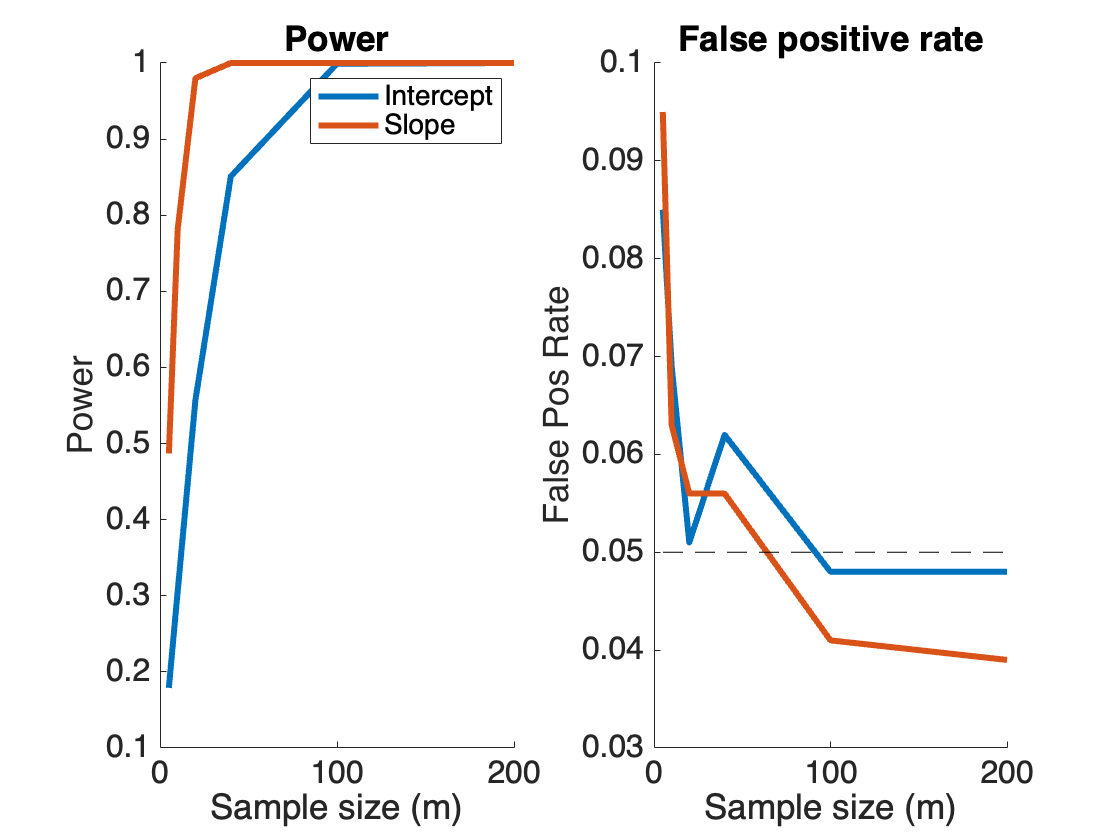


% Plot the results 

figure; 
subplot(1, 2, 1); hold on; set(gca, 'FontSize', 16)
plot(m_vals, power, 'LineWidth', 3);
xlabel('Sample size (m)'); ylabel('Power');
legend({'Intercept' 'Slope'})
title('Power')

subplot(1, 2, 2); hold on; set(gca, 'FontSize', 16)
plot(m_vals, fpr, 'LineWidth', 3);
xlabel('Sample size (m)'); ylabel('False Pos Rate');
plot([min(m_vals) max(m_vals)], [0.05 0.05], 'k--');
title('False positive rate')

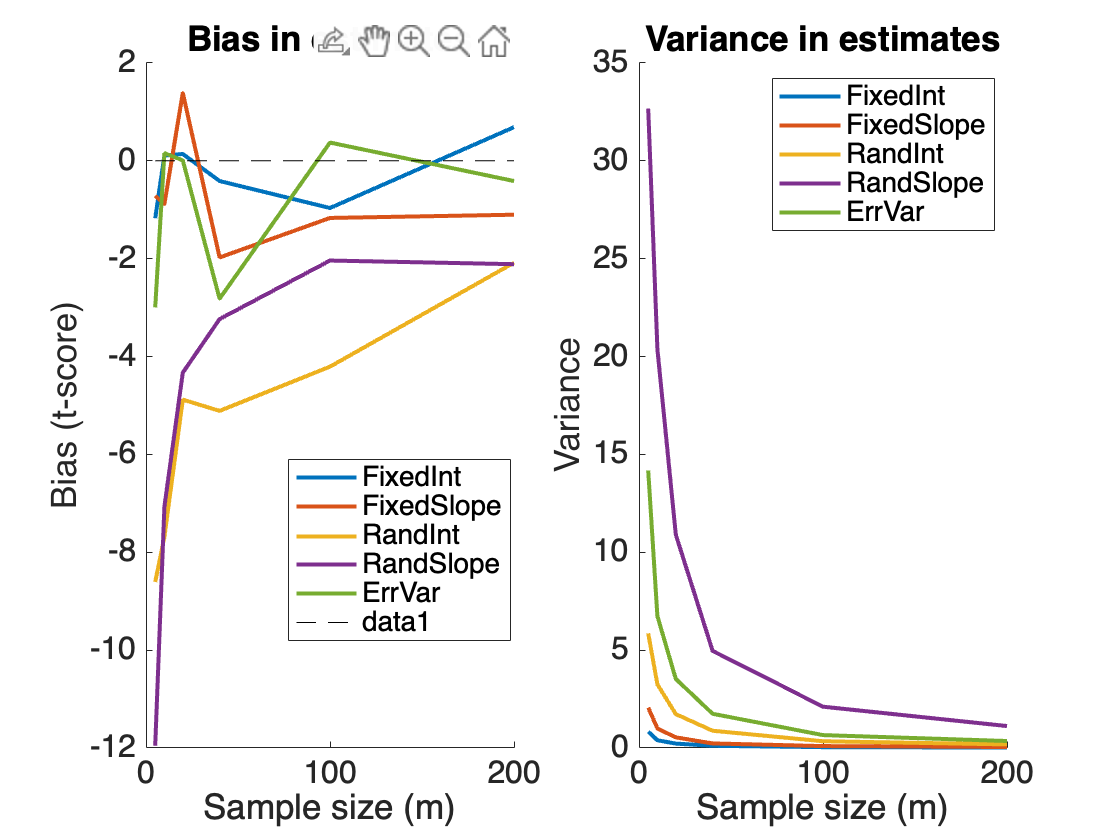


% Plot bias and var   

figure; 
subplot(1, 2, 1); hold on; set(gca, 'FontSize', 16)
plot(m_vals, bias_t, 'LineWidth', 2);
xlabel('Sample size (m)'); ylabel('Bias (t-score)');
legend(bv_tables{1}.Properties.RowNames')
plot([min(m_vals) max(m_vals)], [0 0], 'k--');
title('Bias in estimates')

subplot(1, 2, 2); hold on; set(gca, 'FontSize', 16)
plot(m_vals, variance, 'LineWidth', 2);
xlabel('Sample size (m)'); ylabel('Variance');
legend(bv_tables{1}.Properties.RowNames')
title('Variance in estimates')

subplot(1,2,1)
legend("Position", [0.25717,0.23647,0.19821,0.21548])

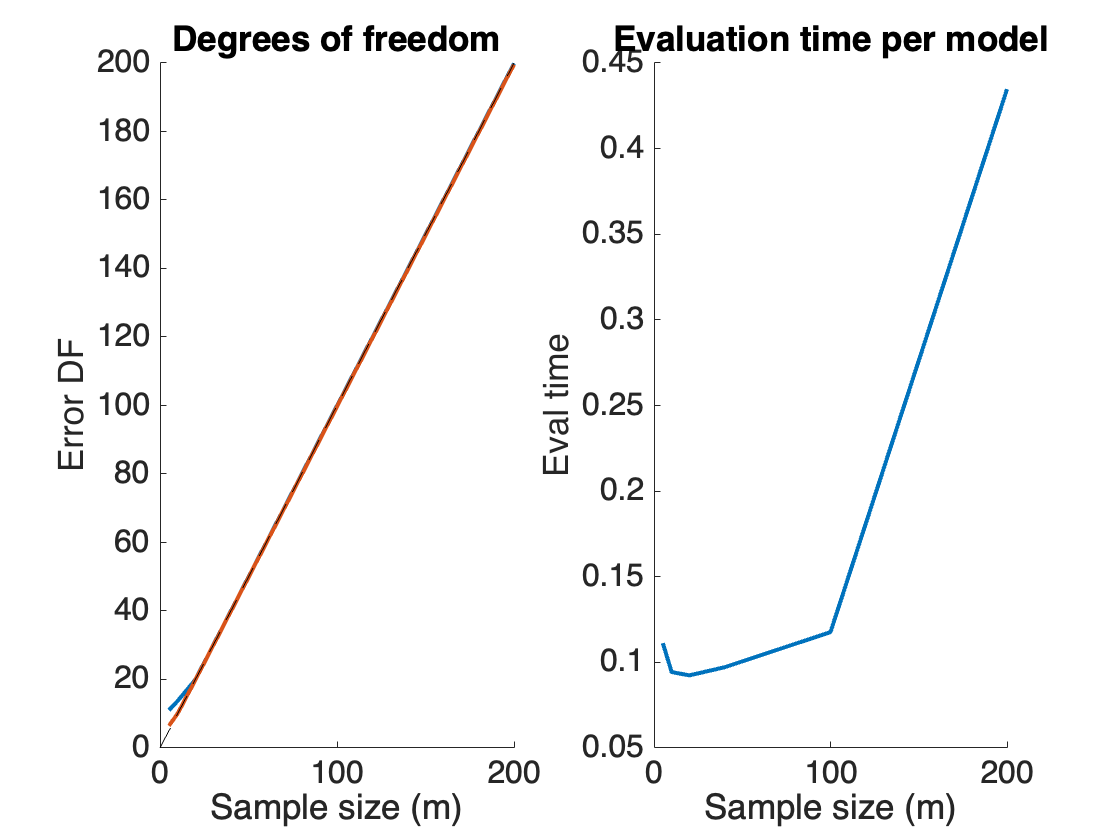


% Plot DFE and eval time   

figure; 
subplot(1, 2, 1); hold on; set(gca, 'FontSize', 16)
plot(m_vals, dfe, 'LineWidth', 2);
xlabel('Sample size (m)'); ylabel('Error DF');
plot([0 max(m_vals)], [0 max(m_vals)], 'k--');
title('Degrees of freedom')

subplot(1, 2, 2); hold on; set(gca, 'FontSize', 16)
plot(m_vals, eval_time_per_model, 'LineWidth', 2);
xlabel('Sample size (m)'); ylabel('Eval time');
title('Evaluation time per model')

% Save like this:

### Activities

Choose something else to vary or explore, and modify the simulation accordingly. 

- **Regressor type**: Do categorical predictor variables (i.e., those from an experimental design) yield different power or FPR levels than continuous predictors?

- **Number of trials within-person**: Which is more important -- the number of participants or the number of trials within-person? Are there diminishing marginal returns of adding more of one or both?

- **Error variance**: Which has a bigger impact -- changing noise variance or variance of random effects? Why? What is the relationship between the two?

- **Missing data**: What is the impact on power and bias when some participants have unequal amounts of data (e.g., missing data)? What is the relative power of the full LME vs. the two-stage summary statistics approach as variation in missing data across participants increases?

- **Heteroscedasticity**: What is the impact on power and bias when some subjects have a larger error variance than others? 

- **Mismodeling**: What is the impact of leaving a grouping variable (random effect) out of the model?  e.g., running an random intercept-only model if there is a random slope for participant?

- **Compare performance of different models**: Compare the power, bias, variance, and DFE above with those from a different model: 

**Here is a summary of some different models you could select from:**

**Two-stage summary stats**:  Unweighted glmfit_multilevel

**Two-stage precision-weighted**: weighted glmfit_multilevel

**Two-stage precision-weighted bootstrap**: weighted glmfit_multilevel boot

**Matab MFX with REML**

**LMER in R with ML**

**LMER in R with REML**

**statsmodels.lm in python**

**bambi in python**

**igls**

**rigls**